## Part A: 

## 1.

Caricamento Data set

clear all
clc
data_dir = "data/";
filename = "prices_fin.xlsx";
table_prices = readtable(data_dir + filename);

Caricamento file Sectors

filename2 = "sectors_fin.xlsx";
table_Sec = readtable(filename2,"TextType","string");

Error using readtable
Unable to find or open 'sectors_fin.xlsx'. Check the path and filename or file permissions.

dt = table_prices(:,1).Variables;
values = table_prices(:,2:end).Variables;
nm = table_prices.Properties.VariableNames(2:end);

myPrice_dt = array2timetable(values, 'RowTimes', dt, 'VariableNames', nm);

start_dt = datetime('11/05/2021', 'InputFormat', 'dd/MM/yyyy');
end_dt   = datetime('11/05/2023', 'InputFormat', 'dd/MM/yyyy');

rng = timerange(start_dt, end_dt, 'Closed');
subsample = myPrice_dt(rng, :);
prices_val = subsample.Variables;
dates = subsample.Time;

N_asset = size(prices_val,2);

LogRet = tick2ret(prices_val, 'Method', 'continuous');

## Variance and Mean

V = cov(LogRet);
ExpRet = mean(LogRet);

## Creation of N random portfolio

N = 100000;
RetPtfs=zeros(1,N);
VolPtfs = zeros(1,N);
SharpePtfs = zeros(1,N);

for n = 1:N
    w = rand(1,N_asset);
    w_norm = w./sum(w);
    %calculate expected return of portfolio
    exp_ret_ptf = w_norm * ExpRet';
    exp_vol_ptf = sqrt(w_norm*V*w_norm');
    sharpe_ratio = exp_ret_ptf/exp_vol_ptf;

    RetPtfs(n) = exp_ret_ptf;
    VolPtfs(n) = exp_vol_ptf;
    SharpePtfs(n) = sharpe_ratio;
end
%%Frontier
fun = @(x) x'*V*x;
ret_ = linspace(0, 0.001, 25);

x0 = rand(1, N_asset)';
x0 = x0/sum(x0);

lb = zeros(1,N_asset);
ub = ones(1,N_asset);
FrontierVol = zeros(1,length(ret_));
FrontierRet = zeros(1,length(ret_));

for i = 1:length(ret_)
    r = ret_(i);
    Aeq = [ones(1,N_asset); ExpRet];
    beq = [1; r];

    w_opt = fmincon(fun, x0, [], [], Aeq, beq, lb, ub);
    min_vol = sqrt(w_opt'*V*w_opt);

    FrontierVol(i) = min_vol;
    FrontierRet(i) = r;
end


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.


Solver

## Plot

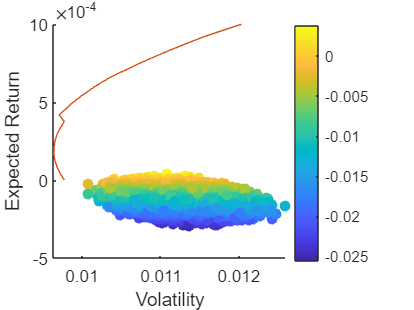

h = figure;
title('Expected Return VS Volatility')
scatter(VolPtfs, RetPtfs, [], SharpePtfs, 'filled')
colorbar
hold on
plot(FrontierVol, FrontierRet)
xlabel('Volatility')
ylabel('Expected Return')


## Minimum Variance Portfolio

Vol_opt = min(FrontierVol)

Vol_opt = 0.0096

Mean_opt = FrontierRet(6)

Mean_opt = 2.0833e-04

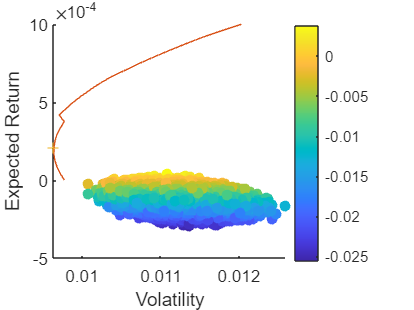

plot(Vol_opt, Mean_opt, '+')

p = Portfolio('AssetList', nm);
p = setDefaultConstraints(p);
Port = estimateAssetMoments(p, LogRet);
pwgt = estimateFrontier(Port, 100);
[pf_risk, pf_Retn] = estimatePortMoments(Port, pwgt);
figure;
title('Expected Return VS Volatility')
scatter(VolPtfs, RetPtfs, [], SharpePtfs, 'filled')
colorbar
hold on
plot(pf_risk, pf_Retn)
xlim([0.006 0.016])
xlabel('Volatility')
ylabel('Expected Return')

Vol_opt = min(pf_risk);
k = find(pf_risk == Vol_opt);
Mean_opt = pf_Retn(k)

Mean_opt = 6.1843e-05

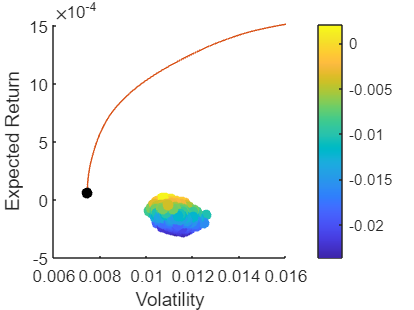

scatter(Vol_opt, Mean_opt,'filled','black')

pwgt(:, k)

ans =          0
    0.0501
         0
         0
         0
         0
         0
    0.0026
         0
         0


Sharpe Ratio

sharpe_vector = zeros(1,100);
for n = 1:100
    sharpe_vector(n) = pf_Retn(n)/sqrt(pf_risk(n));
end
max_sharpe = max(sharpe_vector);
kk = find(max_sharpe ==sharpe_vector)

kk = 94

pwgt(:,kk)

ans =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0
